# Exercise 1

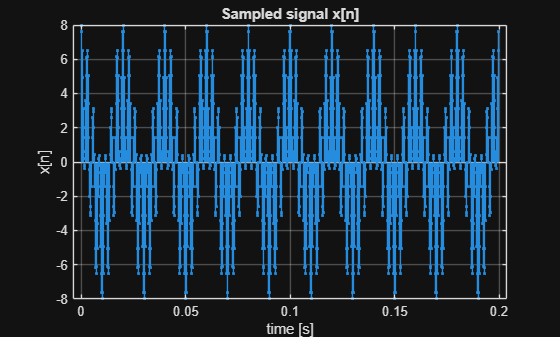


Fs = 5000;              % sampling frequency [Hz]
Ts = 1/Fs;              % sampling period [s]
N  = 1000;              % number of samples

n = 1:N;                % sample indices
t = 0:Ts:(N-1)*Ts;    % 0, Ts, 2Ts, ..., (N-1)Ts Time vector

% Signal Parameters
A1 = 4;  A2 = 4;
F1 = 50; F2 = 350;


%x(t) = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);
% Sampled signal x[n]
x = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);

Df = 1/(N*Ts);
f = [-Fs/2:Df:(Fs/2)-Df];

%a)
% Plot as stem vs time
figure; stem(t, x, '.'); grid on
xlabel('time [s]'); ylabel('x[n]')
title('Sampled signal x[n]')

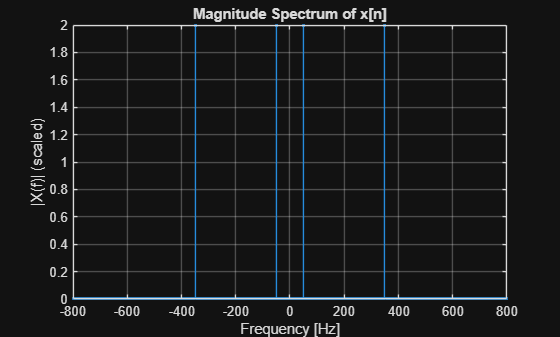


% FFT and frequency axis
X  = fft(x);            % raw FFT
Xc = fftshift(X);       % center zero freq
Xc = Xc / N;            % scale by N

Df = Fs/N;              % frequency spacing [Hz]

% Plot magnitude spectrum
figure;
stem(f, abs(Xc), '.'); grid on
xlabel('Frequency [Hz]');
ylabel('|X(f)| (scaled)');
title('Magnitude Spectrum of x[n]');
xlim([-800 800]);

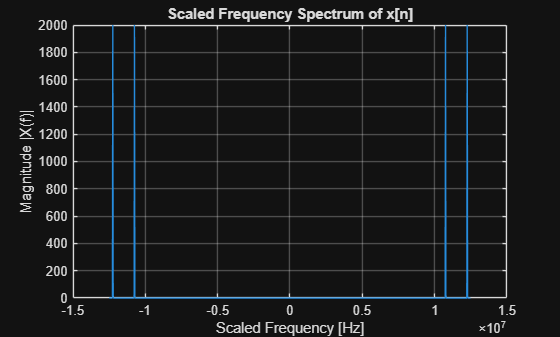



%c)
%plot the scaled (N dependent) absolute value (abs) of the spectrum as
%function of f*Fs.
scaledFreq = f * Fs; % Scale frequency by sampling frequency
figure; plot(scaledFreq, abs(X)); grid on
xlabel('Scaled Frequency [Hz]'); ylabel('Magnitude |X(f)|')
title('Scaled Frequency Spectrum of x[n]')

## Exercise 1-B

clear;
clc;
%a) Define the vectors a and b 

% --- Sampling setup (from 1-A) ---
Fs = 5000;             
Ts = 1/Fs;             
N  = 1000;             
n  = 1:N;              
t  = (n-1)*Ts; 

b = [0.398 -0.398];
a = [1 -0.6796];

A1 = 4;  A2 = 4;
F1 = 50; F2 = 350;

x  = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);

%b) calculate the discrete output signal y[n] using the filter command

y = filter(b,a,x)

y =     3.1840    2.0092    0.9303   -0.0023   -0.7176   -1.1530   -1.2768   -1.1012   -0.6851   -0.1261    0.4559    0.9400    1.2262    1.2537    1.0123    0.5436   -0.0669   -0.7060   -1.2549   -1.6116   -1.7104   -1.5342   -1.1185   -0.5436    0.0798    0.6321    1.0075    1.1339    0.9872    0.5951    0.0325   -0.5930   -1.1618   -1.5647   -1.7239   -1.6078   -1.2371   -0.6805   -0.0420    0.5588    1.0100    1.2280    1.1740    0.8611    0.3517   -0.2542   -0.8381   -1.2856   -1.5082   -1.4601


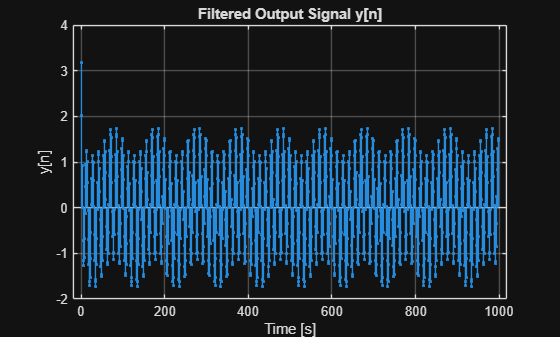


%c) plot y[n] as a stem plot as function of time.

t = 0:1:;

figure; stem(t, y, '.'); grid on
xlabel('Time [s]'); ylabel('y[n]')
title('Filtered Output Signal y[n]');

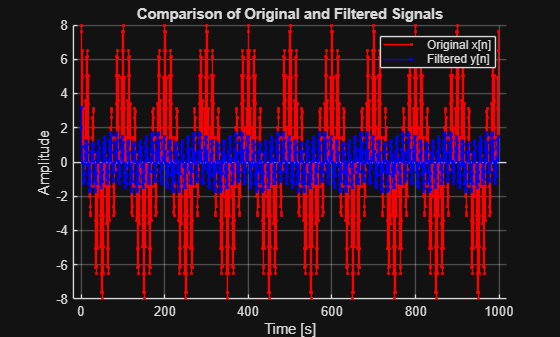


%d) Compare y[n] with x[n] and discuss what frequency component appears to have been filtered away, i.e. the low frequency component, F1, or the high frequency component, F2.

% Compare the original and filtered signals
figure; 
hold on; 
stem(t, x, 'r.', 'DisplayName', 'Original x[n]'); 
stem(t, y, 'b.', 'DisplayName', 'Filtered y[n]'); 
grid on;
xlabel('Time [s]'); 
ylabel('Amplitude');
title('Comparison of Original and Filtered Signals');
legend show;

## Exercise 1-C

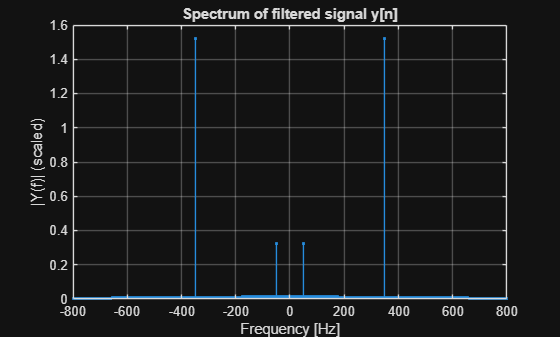

clear; clc

% --- Sampling setup (from 1-A) ---
Fs = 5000;             
Ts = 1/Fs;             
N  = 1000;             
n  = 1:N;              
t  = (n-1)*Ts;         

% --- Two-tone input x[n] (from 1-A) ---
A1 = 4;  A2 = 4;
F1 = 50; F2 = 350;
x  = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);   % length 1000

% --- Filter (your 1-B coefficients) ---
b = [0.8398 -0.8398];
a = [1 -0.6796];
y = filter(b, a, x);                          % length 1000

% --- FFT of y[n] ---
Yc = fftshift( fft(y) ) / N;                  % centered, scaled
Df = Fs/N;
f  = (-N/2:N/2-1) * Df;

% --- Plot ---
figure;
stem(f, abs(Yc), '.'); grid on
xlabel('Frequency [Hz]'); ylabel('|Y(f)| (scaled)')
title('Spectrum of filtered signal y[n]')
xlim([-800 800])

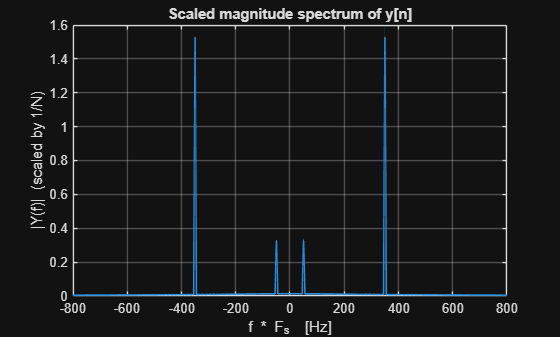


%b) plot the scaled (N dependent) absolute value (abs) of the spectrum as function of f*Fs.


% Normalized frequency f = k/N   (from -0.5 to 0.5)
f_norm = (-N/2 : N/2-1) / N;      

% Physical frequency f*Fs  (in Hz)
f_Hz = f_norm * Fs;              

% --- Plot scaled magnitude spectrum ---
figure;
plot(f_Hz, abs(Yc), 'LineWidth', 1.2);
grid on;
xlabel('f * F_s  [Hz]');
ylabel('|Y(f)|  (scaled by 1/N)');
title('Scaled magnitude spectrum of y[n]');
xlim([-800 800]);


%c)Find the output amplitude values of the filtered signal at F1 and F2
% --- Magnitudes at the two tones for y[n] ---
Df = Fs/N;
targets = [50 350];                 % Hz

for f0 = targets
    k = round(f0/Df);               % bin offset from DC
    idx_pos = N/2 + 1 + k;          % +f0 index in fftshifted array
    fprintf('f = %3d Hz: |Y| = %.6f\n', f0, abs(Yc(idx_pos)));
end

f =  50 Hz: |Y| = 0.325788
f = 350 Hz: |Y| = 1.523287




%d) Calculate the ratio between filtered output signal and input signal at F1 and F2

% Input spectrum (scaled like Yc)
Xc = fftshift( fft(x) ) / N;

targets = [50 350];
Df = Fs/N;

for f0 = targets
    k = round(f0/Df);
    idx = N/2 + 1 + k;
    Xmag = abs(Xc(idx));
    Ymag = abs(Yc(idx));
    ratio = Ymag / Xmag;
    fprintf('f=%3d Hz: |X|=%.6f, |Y|=%.6f, |Y|/|X|=%.6f\n', f0, Xmag, Ymag, ratio);
end

f= 50 Hz: |X|=2.000000, |Y|=0.325788, |Y|/|X|=0.162894
f=350 Hz: |X|=2.000000, |Y|=1.523287, |Y|/|X|=0.761644
